# Práctica 7. Estabilidad y EDOs Rígidas

El objetivo de esta práctica es estudiar la estabilidad absoluta de algunos métodos mono y multipaso


$$\mathrm{(PVI)} \qquad \begin{cases}
\frac{d\mathbf{u}}{dt} (t) = \mathbf f (t, \mathbf u (t)) & t \in [t_0, T], \\
\mathbf u(t_0) = \mathbf u_0 
\end{cases}$$


## 1 Estabilidad del método RK4

### 1.A Cálculo de R. 

Utilizando las fórmulas de $\Phi$ para RK4 implementadas en la Práctica 5b y variables simbólicas $u,\lambda, h, z$, comprobar la fórmula de la función $R$ deducida en teoría.

Se recomienda utilizar las funciones simbólicas `simplify`  y  `subs.`

clear all
clc
syms u lambda h z
f = @(u)[lambda*u];
F1 = f(u);
F2 = f(u + h * F1/2);
F3 = f(u + h * F2/2);
F4 = f(u + h * F3);
R = u + h/6 * (F1 + 2*F2 + 2*F3 + F4);
R = simplify(R)/u;
R = subs(R,h,1);   %Sustituimos h por 1 y en el siguienete lambda por z.
R = subs(R,lambda,z)  %Vemos que es la misma fórmula que la hallada en teoría.

$$R = \frac{z^{4}}{24}+\frac{z^{3}}{6}+\frac{z^{2}}{2}+z+1$$

### 1.B Representar la región de estabilidad

Representar la región de estabilidad $S = \{ z \in \mathbb C : |R(z)| \le 1 \}$en el plano complejo utilizando la función `contour` de MATLAB utilizando la función anterior.

**Indicación.** Las funciones `contour` y `contourf` de MATLAB permiten pintar curvas de nivel.

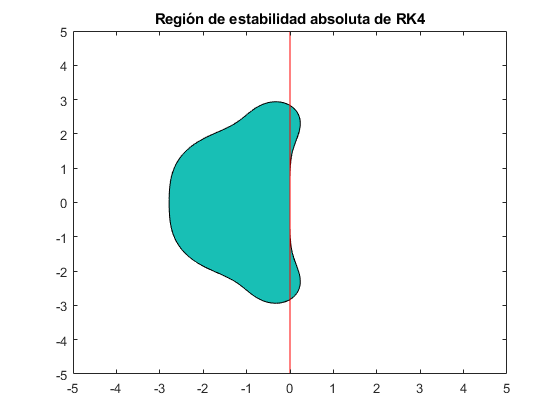

clear all
clc
% Dibujo de la región de estabilidad
[X,Y] = meshgrid(-5:0.01:5,-5:0.01:5);

Z = X + i * Y;   % Numeros complejos de la malla

Rfunc = @(z) [1 + z + 1/2 * z.^2 + 1/6 * z.^3 + 1/24 * z.^4]; %polinomio obtenido anteriormente

Rmat = Rfunc(Z);  % Valores de R sobre la malla
Rhat = 1-abs(Rmat);  % MATLAB pinta por defecto el conjunto
contourf(X,Y,Rhat,[0,0])
hold on
plot([0,0],[-5,5],'r')  %Para poner la línea del 0
title('Región de estabilidad absoluta de RK4')
hold off

## 2. Estabilidad del Método AB4

2.1 Escribir el polinomio $\pi_z(w)$ de estabilidad correspondiente al método AB2


$$U_{i+1} = U_i + \frac h 3 (3 f_i - f_{i-1})$$


y calcular las simbólica raíces $\mu_1(z), \mu_2(z)$ respecto $w$ utilizando el comando `solve` de MATLAB.

syms z w
piz = @(w) (w^2 - (1 + 3/2 * z) * w + z/2);
u = solve(piz,w)   % Estas son las raíces que nos saca la función solve

$$u = \left(\begin{array}{c} \frac{3\,z}{4}-\frac{\sqrt{\frac{9\,z^{2}}{4}+z+1}}{2}+\frac{1}{2}\\ \frac{3\,z}{4}+\frac{\sqrt{\frac{9\,z^{2}}{4}+z+1}}{2}+\frac{1}{2} \end{array}\right)$$

2.2 Representar la región de estabilidad $\{ z \in \mathbb C : |\mu_1(z)| \le 1\} \cap \{ z \in \mathbb C : |\mu_2(z)| \le 1\}$

**Indicación.** Una opción sencilla (aunque poco eficiente) de construir la región es hacer un barrido del espacio y construir una matriz con 0 en los puntos que no son del conjunto y 1 en los que sí.

**Indicación 2. **Una forma más eficiente de hacer lo mismo, es construir las matrices de ambas regiones mediante fórmulas vectoriales, e intersecar haciendo productos componente a componente.

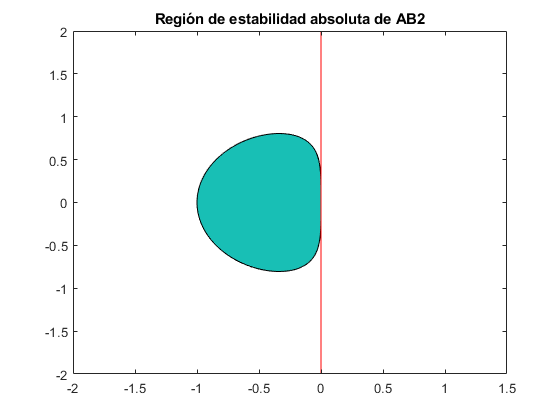

% dibujo de la región de estabilidad
[X,Y] = meshgrid(-2:0.01:1.5,-1.5:0.01:2);

Z = X + i * Y; % Numeros complejos de la malla

u1 = @(z) [3*z/4 - (sqrt((9*(z.^2))/4 + z + 1)/2) + 1/2]; % polinomios obtenidos anteriormente
u2 = @(z) [3*z/4 + (sqrt((9*(z.^2))/4 + z + 1)/2) + 1/2];

u1mat = u1(Z); % Valores de R sobre la malla
u2mat = u2(Z);

u1hat = 1 - abs(u1mat);
u2hat = 1 - abs(u2mat);
uhat = u1hat .* u2hat; % Multiplicamos componente a componente

contourf(X,Y,uhat,[0,0])
hold on
plot([0,0],[-2,2],'r')  % Para poner la línea del 0
hold off
title('Región de estabilidad absoluta de AB2')

## 3. Inestabilidad numérica

Para la ecuación $u' = -\mu (u - 1)$ , $u(0) = 0$ aplicar el método de Euler explícito e Crank-Nicolson (copiándolos de la Práctica 5 al apéndice) al PVI para comprobar los efectos de inestabilidad que se dan el primero. Representar también la solución explícita. 

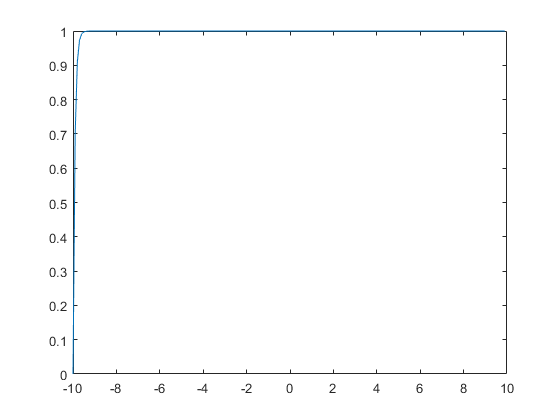

f = @(t,u) -7*(u-1);
u_0 = 0;
t_interv = [-10,10];
h = 0.1;
N = 20/h;
[t,U]=Euler_explicito_1D(f,t_interv,u_0,N);
% Representamos la solución hallada con Euler explícito.
plot(t,U)

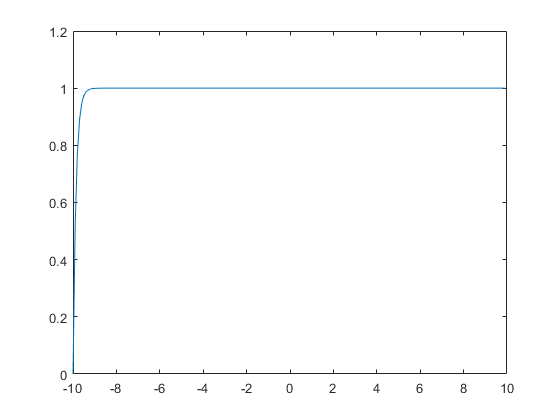




[t,U]=CrankNicolson(f,t_interv,u_0,N);
% Representamos la solución hallada con Crank-Nicolson.
plot(t,U)

## Apéndice

### A1. Euler explícito

function [t,U]=Euler_explicito_1D(f,t_interv,u_0,N)

% Conocemos el tiempo inicial t_0 (t_interv(1)) y el tiempo final
% T (t_interv(2))

t_0 = t_interv(1);
T = t_interv(2);

% También conocemos la función f y el número de pasos N.
% Además sabemos el valor inicial u_0

% Calculamos el paso h:
h = (T - t_0) / N;

% Inicializamos el vector U donde meteremos los U_i
U = zeros(N,1);
U(1) = u_0;

% También inicializamos el vector T donde metemos los t_i, siendo 
% el t_0 el primero.
t = zeros(N,1);
t(1) = t_0;

% Calculamos el resto de U_i y t_i:
for i = 1 : (N-1)
    U(i+1) = U(i) + h * f(t(i),U(i));
    t(i+1) = t(i) + h;
end

end

### A2. Crank-Nicolson

function [t,U]=CrankNicolson(f,t_interv,u_0,N)
syms x
t_0 = t_interv(1);
T = t_interv(2);
h = (T-t_0)/N;
t(1) = t_0;
U(1) = u_0;
for i=1:N-1
    t(i+1) = t(i) + h;
    %Para resolver la ec. implícita usamos el comando vpasolve.
    eqn = x- U(i)-h*(1/2*f(t(i),U(i))+1/2*f(t(i+1),x)) == 0;
    U(i+1) = vpasolve(eqn,x);
end
end